clc
clear


load fisheriris
A.features = meas(:,1:4);
Y = species;

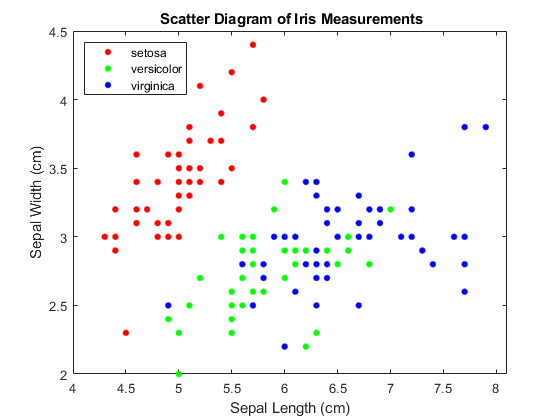

figure
gscatter(A.features(:,1),A.features(:,2),Y);
h = gca;
lims = [h.XLim h.YLim]; % Extract the x and y axis limits
title('{\bf Scatter Diagram of Iris Measurements}');
xlabel('Sepal Length (cm)');
ylabel('Sepal Width (cm)');
legend('Location','Northwest');

% print('results/fisher_iris_visual', '-dpng', '-r600')

### Preprocessing

A.means = mean(A.features,1);
A.devs = std(A.features,1);

% normalize
for i = 1:size(A.features,2)
    A.X(:,i) = (A.features(:,i) - A.means(i))/(A.devs(i));
end


### Perform PCA

[A.loadings, A.scores, PCA_latent_A, PCA_tsquared_A, PCA_explained_A, PCA_mu_A] = pca(A.X);

### Setup plotting

% Line styles
line_width = 0.8;

% Colours
blue  = '#06ACE9';
white = '#FFFFFF';

### Scree plot

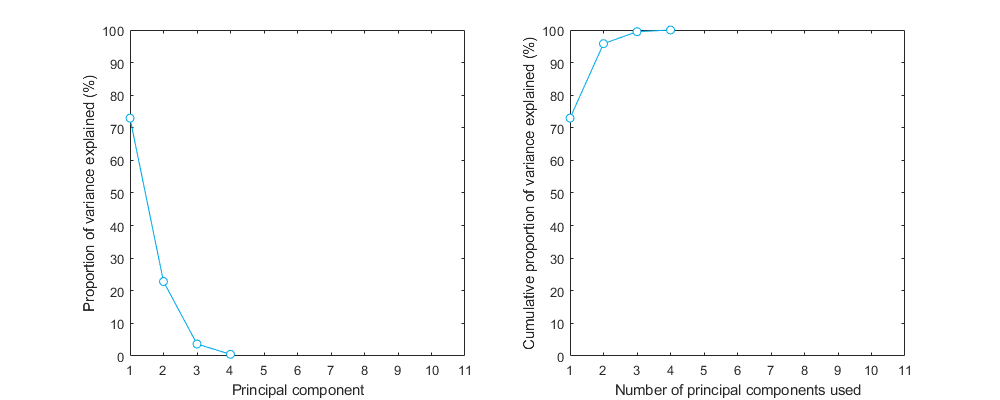

% Create the scree plot figure
figure()

% Plot the proportion of variance explained
subplot(1,2,1)
plot(PCA_explained_A, '-o', 'LineWidth',line_width, 'Color', blue, 'MarkerFaceColor', white, 'MarkerEdgeColor', blue, 'MarkerSize', 6)
ylabel("Proportion of variance explained (%)")
xlabel("Principal component")
ylim([0 100])
xlim([1 11])
xticks([1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11])

% Plot the cumulative proportion of variance explained
subplot(1,2,2)
plot(cumsum(PCA_explained_A), '-o', 'LineWidth',line_width, 'Color', blue, 'MarkerFaceColor', white, 'MarkerEdgeColor', blue, 'MarkerSize', 6)
ylabel("Cumulative proportion of variance explained (%)")
xlabel("Number of principal components used")
ylim([0 100])
xlim([1 11])
xticks([1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11])

% Set the plot size
fig_scree_plot = gcf;
fig_scree_plot.Position(3:4) = [1000, 400];

### Choose number of components

PCA_components = 2;

## Reduce PCA 

% singular value matrix
SIGMA = diag(PCA_latent_A);
SIGMA_inv = inv(SIGMA);

% reduced matrices
SIGMA_reduced = diag(PCA_latent_A(1:PCA_components));
SIGMA_reduced_inv = inv(SIGMA_reduced);
PCA_loadings_reduced = A.loadings(:, 1:PCA_components);
scores_reduced = A.scores(:, 1:PCA_components);

X = scores_reduced;


SVMModels = cell(3,1);
classes = unique(Y);
rng(1); % For reproducibility

for j = 1:numel(classes)
    indx = strcmp(Y,classes(j)); % Create binary classes for each classifier
    SVMModels{j} = fitcsvm(X,indx,'ClassNames',[false true],'Standardize',true,...
        'KernelFunction','rbf','BoxConstraint',1);
end

d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(X(:,1)):d:max(X(:,1)),...
    min(X(:,2)):d:max(X(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];
N = size(xGrid,1);
Scores = zeros(N,numel(classes));

for j = 1:numel(classes)
    [~,score] = predict(SVMModels{j},xGrid);
    Scores(:,j) = score(:,2); % Second column contains positive-class scores
end

[~,maxScore] = max(Scores,[],2);

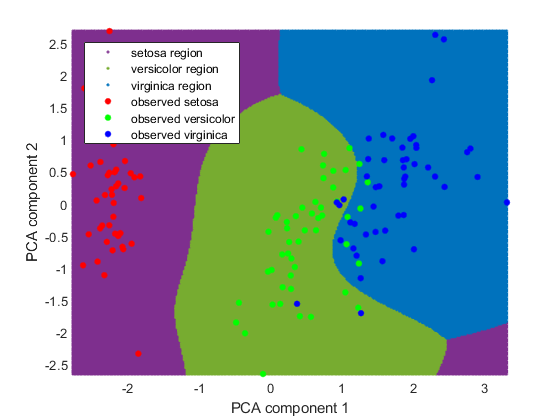

figure
h(1:3) = gscatter(xGrid(:,1),xGrid(:,2),maxScore,...
    [0.1 0.5 0.5; 0.5 0.1 0.5; 0.5 0.5 0.1]); 
set(h(1), 'Color', "#7E2F8E");
set(h(2), 'Color', "#77AC30");
set(h(3), 'Color', "#0072BD");
hold on
h(4:6) = gscatter(X(:,1),X(:,2),Y);
xlabel('PCA component 1');
ylabel('PCA component 2');
legend(h,{'setosa region','versicolor region','virginica region',...
    'observed setosa','observed versicolor','observed virginica'},...
    'Location','Northwest');
axis tight
hold off
print('results/SVM_radial_visual', '-dpng', '-r600')